videoSource = VideoReader('viptraffic.avi');

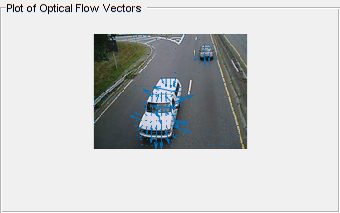

% opticFlow = opticalFlowLK('NoiseThreshold', 0.009);
opticFlow = opticalFlowHS();
h = figure;
movegui(h);
hViewPanel = uipanel(h,'Position',[0 0 1 1],'Title','Plot of Optical Flow Vectors');
hPlot = axes(hViewPanel);
i = 1;
while hasFrame(videoSource)
    frameRGB = readFrame(videoSource);
    frameGray = im2gray(frameRGB);
    flow = estimateFlow(opticFlow, frameGray);
%     if i == 1
%         imshow(frameRGB);
%         hold on
%         plot(flow,'DecimationFactor',[5 5],'ScaleFactor',60,'Parent',hPlot)
%     end
    if i == 41
        imshow(frameRGB);
        hold on
        plot(flow,'DecimationFactor',[5 5],'ScaleFactor',60,'Parent',hPlot)
    end
%     if i == 91
%         imshow(frameRGB);
%         hold on
%         plot(flow,'DecimationFactor',[5 5],'ScaleFactor',60,'Parent',hPlot)
%     end
    i = i + 1;
end